# Aula 10 - Laboratório de Controle - 2023/1

## Projeto do controlador avanço-atraso para o motor CC

## **Nomes:   **

Esta aula visa realizar o projeto dos controladores avanço e atraso de fase, avaliando-os em simulação e no motor CC. 

Após obter o modelo do motor para uma dada rotação, avalia-se o efeito das escolhas dos projetos.

if ~exist('obj')
    z=seriallist;
    comPort=z{length(z)};
    obj=serial(comPort,'BaudRate',9600);
    obj.Terminator='CR';
    fopen(obj);
end
datetime

**Obtenção da resposta de velocidade do motor CC **

Este teste verifica o bom funcionamento do motor e fornece os parâmetros iniciais para definir a velocidade de operação.

Execute a seção abaixo.

Ts=20;
Tempo=1;
U0=[70 100 170]; 
[y,t, yr, tau] = arduino_coleta_motor(obj,U0,Tempo);
seta_saida_motor(obj,0); 
figure;
plot(y);title('Figura 1. Resposta para a aplicação de degraus de mesma amplitude em MA');
xlabel('Amostras');ylabel('RPM')
RPM=yr;
U00=U0;

**Obtenção dos dados para o modelo que relaciona o sinal PWM com a velocidade em RPM**

Escolha uma velocidade Ref em torno da qual o motor deverá operar, a partir da observação da Figura 1. 

O próximo teste gerará dados (dat1) em torno da rotação escolhida para obter os modelos.

Basta executar a seção a seguir.  Caso os dados fiquem ruins, repita a coleta de dados.

Ref=0; % Escolha antes um valor de Ref para velocidade
Ref1=Ref+200;
Tempo=2; 
r0=floor(interp1(RPM,U00,Ref));
if isnan(r0)
    beep
    disp('**** Escolha ruim de Ref ***')
    return
end
d1=[0 0 5 10 5 8];
U20=r0+d1; 
u0=ones(100,1);
U2=[];
for i=1:6
    U2=[U2;u0*U20(i)];
end
[y,t,yr,tau] = arduino_coleta_motor(obj,U20,Tempo);
seta_saida_motor(obj,0); 

U2=U2(150:end);
Y2=y(150:end);
t=[0:(length(Y2)-1)]*Ts/1000;
y0=mean(Y2(1:50));
yn=Y2-y0;
dat1=iddata(yn,U2-U2(1),Ts/1000); 

figure;
plot(t,Y2);title('Figura 2. Resposta para a rotação escolhida');
xlabel('Amostras');
figure;
plot(t,U2);title('Figura 3. Degraus aplicados');
xlabel('Amostras');

Nesta seção são obtidos os modelos de ordem 1 e 2. Caso o modelo de ordem 2 fique ruim, outro método é proposto na próxima seção.

g1e=procest(dat1,'P1');
g2e=procest(dat1,'P2');
polo_minimo=min(abs(pole(g2e)))
g1=tf(g1e.Kp,[g1e.Tp1 1])
figure;
compare(dat1,g1e,g2e);
title('Figura 4: Avaliação dos modelos obtidos');

Nesta seção há outra alternativa para estimar o modelo de ordem 2, caso o da seção anterior tenha ficado ruim. 

g2ea=arx(dat1,[2 2 1]);
ys=step(g2ea);
dat1s=iddata(ys,ones(size(ys)),Ts/1000);
g2e=procest(dat1s,'P2');
polo_minimo=min(abs(pole(g2e)))
figure;
compare(dat1,g2e);


Caso o modelo de ordem 2 tenha ficado bom agora, pode seguir. Se  o modelo de ordem 2 anterior seja melhor, execute a seção anterior novamente.

**Se um dos polos do modelo de ordem 2 for muito próximo de zero (polo_minimo < 1e-3), repita a identificação, podendo alterar um pouco Ref.**

**O projeto dos compensadores avanco e atraso será feito com o modelo de ordem 2.**

**Atividade 1: Obtenção de uma resposta de referência usando o método de sintonia lambda e o controlador PI.**

Nós métodos de resposta em frequência, a margem de fase é utilizada para a escolha dos compensadores. Usaremos o projeto já realizado do controlador PI via método lambda para obter uma boa resposta a ser usada como referência para os projetos de resposta em frequência.

Para isso, escolha um valor adequado de lambda para obter uma boa resposta com um controlador PI. 

O ganho K e a constante de  tempo tau vem de g1.

1.1 Escolha lambda baseando-se na constante de tempo de malha aberta, como no relatório da aula 9, de modo a obter uma boa resposta.

lambda=0; % Escolher
if (lambda<=0)
    beep;
    disp('lambda deve ser > 0');
    return
end
K=g1e.Kp;
tau=g1e.Tp1;
Kp=tau/(K*lambda); 
Ki=1/tau;
[y,u,t] = arduino_controle_PI_motor(obj,Ref,Tempo, Kp, Ki); 
[y,u,t] = arduino_controle_PI_motor(obj,Ref1,Tempo, Kp, Ki); 
seta_saida_motor(obj,0);
nr=Ref1-mean(y(1:3));
iae=trapz(t,100*abs(Ref1-y)/nr); 
ss=sprintf('Figura 5. Resposta do PI - IAE = %.0f',iae);
r=Ref1*ones(size(y));
figure;
subplot(211);plot(t,[y 1.01*r 0.99*r]);title(ss);
subplot(212);plot(t,u);title('Figura 6. Sinal de controle para lambda selecionado');

**As duas barras na figura mostram o limite do erro em regime (1%).**

Como o modelo do motor é tipo 1 e os compensadores avanço e atraso não têm polo na origem (como o PI), deve-se obter um ganho para atender o erro em regime. 

Esse ganho também deve conseguir uma resposta rápida como a obtida com o controlador PI. 

Especificaremos para os controladores avanço e atraso UPe=3%, que corresponde a $\zeta=0.75$. 

Também especificaremos um erro em regime menor que 1%.

1.2 Obtenha o tempo de estabelecimento aproximado da Figura 5  e substitua abaixo em tse. 

Calcule o ganho  $K_c$ do controlador  para atender o erro em regime, lembrando que ele é dador por  $E=\frac{1}{K_cK}$, onde $K$é o ganho da FT de MA. 

IMPORTANTE: talvez esse ganho precise ser aumentado para atender a especificação de tempo de estabelecimento tse.

Observe abaixo o gráfico de Bode de $G(s)$ e as margens de fase e ganho correspondentes às especificações feitas. A margem de fase do gráfico de Bode de G(s) será usada como referência para os projetos dos compensadores de avanço e atraso, em substituição ao amortecimento $\zeta$ usado nos projetos no tempo.

Resposta: 

g2=tf(g2e.Kp,conv([g2e.Tp1 1],[g2e.Tp2 1]));
UPe=3;
tse=0; % Obter da figura 3
zeta=0.75;
figure
[~,MFg2]=margin(Kc*g2);
MFg2=floor(MFg2);
UP=UPe;ts=tse;
Especificacoes_1=table(UP,ts,zeta,MFg2, Erro)
figure;bode(g2,Kc*g2);legend('g2','Kc*g2');
title('Figura 7 - Gráfico de Bode de malha aberta do sistema especificado');grid

1.3 Verifique o efeito do ganho Kc na margem de fase, comparando a margem de fase antes e após a adição deste ganho.  

 Resposta:

**Atividade 2: Projeto do controlador atraso**

O projeto do controlador atraso é mostrado na figura abaixo. A curva de módulo deve ser reduzida de forma que cruze em 0dB na frequência onde a margem de fase será a desejada.

Use o gráfico de Bode de malha aberta de Kc*g2 mostrado na Figura 7 para ver quanto o módulo deve ser reduzido.

Resposta:

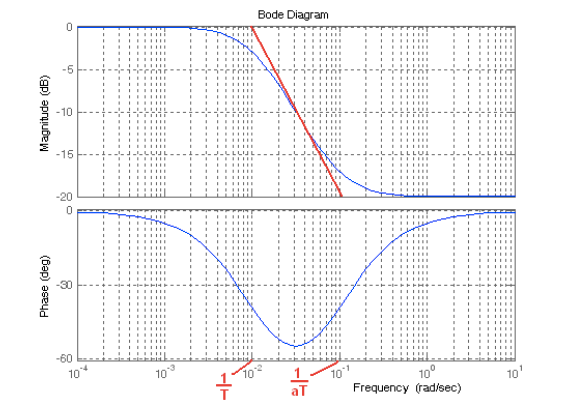

O script a seguir testa em simulação diferentes valores de margem de fase desejada (MFd) usando a função projat.

MFa=[]; % Margem de fase obtida com o projeto
ts=[];UP=[]; % ts e UP obtidos com o projeto
MFd=linspace(MFg2+10,90,5); % Margem de fase desejada (altere se precisar)
for i=1:length(MFd)
    [c1,a1, T1]=projat(g2,Kc,MFd(i));
    [~,mf]=margin(c1*g2);
    S=stepinfo(feedback(c1*g2,1));
    MFa(i,1)=mf;
    UP(i,1)=S.Overshoot;
    ts(i,1)=S.SettlingTime;
end
MFd=floor(MFd');
MFa=floor(MFa);
Tabela1=table(MFd,MFa,UP,ts)
c11=projat(g2,Kc,MFd(3));
c12=projat(g2,Kc,MFd(5));
figure;
bode(Kc*g2,c11*g2,c12*g2);title('Figura 8. Diagrama de Bode');grid;
legend('Kc*g2',num2str(MFd(3)),num2str(MFd(5)))

m1=feedback(c11*g2,1);
m2=feedback(c12*g2,1);
figure
step(m1,m2);title('Figura 9. Resposta ao degrau de dois controladores atraso')
legend(num2str(MFd(3)),num2str(MFd(5)));

2.1 Qual o efeito de aumentar MFd sobre o gráfico de Bode compensado?

Resposta:

2.2 Qual o efeito de  aumentar MFd sobre a resposta ao degrau?

Resposta:

**Atividade 3: Teste do compensador atraso projetado no motor **

Selecione o compensador que achar mais adequado (ver Tabela 1) e teste no motor.

MFda=0; % Escolher um valor de MF desejada (MFDa) de acordo com a Tabela 1
Kcat=1*Kc; % Reveja a escolha do ganho Kca do controlador se a resposta ficar lenta
[c1,a1, T1]=projat(g2,Kcat,MFda);
[y,u,t] = arduino_controle_av_ou_at_motor(obj,Ref,Tempo, a1, T1, Kcat);
[y,u,t] = arduino_controle_av_ou_at_motor(obj,Ref1,Tempo, a1, T1, Kcat);
seta_saida_motor(obj,0);

figure;
nr=Ref1-mean(y(1:3));
iae=trapz(t,100*abs(Ref1-y)/nr); 
r=Ref1*ones(size(y));
ss=sprintf('Figura 10. Saída - IAE = %.0f',iae);
figure;
subplot(2,1,1);
stairs(t,[y 1.01*r 0.99*r]);title(ss);
subplot(2,1,2);
stairs(t,u);title('Controle');

3.1 Verifique o atendimento das especificações (erro, UP, ts, IAE) e compare com o controlador PI.

Resposta:

## Atividade 4 - Projeto do controlador Avanço

O projeto do controlador avanço é mostrado na figura abaixo. Deve-se adicionar fase próximo a frequência em que o módulo cruza 0dB de modo que a margem de fase atual mais a adicionada seja igual à desejada.

Use o gráfico de Bode de malha aberta de Kc*g2 mostrado na Figura 7 para ver quanta fase deve ser adicionada.

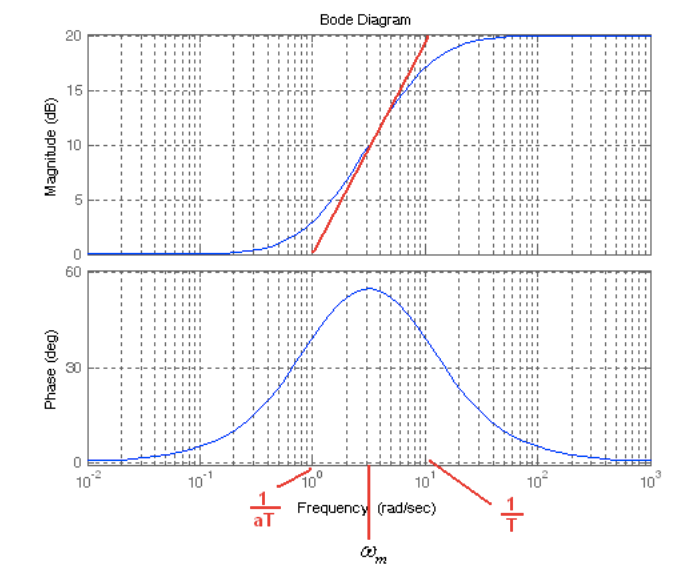

O script a seguir testa diferentes valores de margem de fase adicionada (fi)

MFa=[]; % Margem de fase obtida com o projeto
ts=[];UP=[]; % ts e UP obtidos com o projeto
fi=linspace(5,60,5); % Valores de fase a adicionar à margem de fase atual (altere se ficar melhor)
for i=1:length(fi)
    [c2,a2, T2]=projav(g2,Kc,fi(i));
    [~,mf]=margin(c2*g2);
    S=stepinfo(feedback(c2*g2,1));
    MFa(i,1)=mf;
    UP(i,1)=S.Overshoot;
    ts(i,1)=S.SettlingTime;
end
fi=floor(fi');
MFa=floor(MFa);
Tabela2=table(fi,MFa,UP,ts)
c21=projav(g2,Kc,fi(3));
c22=projav(g2,Kc,fi(5));
figure;
bode(Kc*g2,c21*g2,c22*g2);title('Figura 11. Gráficos de Bode')
legend('Kc*g2',num2str(fi(3)),num2str(fi(5)));grid;
m1=feedback(c21*g2,1);
m2=feedback(c22*g2,1);
figure
step(m1,m2);title('Figura 12. Resposta ao degrau de dois controladores avanço')
legend(num2str(fi(3)),num2str(fi(5)));

4.1 Qual o efeito sobre o gráfico de Bode compensado ao se aumentar o valor da fase adicionada fi?

Resposta:

4.2 Qual o efeito sobre a resposta ao degrau ao se aumentar fi?

Resposta:

**Atividade 5: Teste o compensador avanço projetado no motor **

fi_a=0; % Escolher um valor de fi da tabela 2
Kcav=1*Kc; % Verifique se o ganho Kc deve ser maior para atender tse
[c2,a2, T2]=projav(g2,Kcav,fi_a);
[y,u,t] = arduino_controle_av_ou_at_motor(obj,Ref,Tempo,  a2, T2, Kcav);
[y,u,t] = arduino_controle_av_ou_at_motor(obj,Ref1,Tempo,  a2, T2, Kcav);
seta_saida_motor(obj,0);

figure;
nr=abs(Ref1-mean(y(1:3)));
iae=trapz(t,100*abs(Ref1-y)/nr); 
r=Ref1*ones(size(y));
ss=sprintf('Figura 13. Resposta controlador avanço - IAE = %.0f',iae);
subplot(2,1,1);
stairs(t,y);hold on;plot(t, r,'Color','g');title(ss);hold off
subplot(2,1,2);
stairs(t,u);title('Controle');

6.1 Verifique o atendimento das especificações (erro, UP, ts, IAE) comparando com o atraso e PI

Resposta:

**Atividade 7: Projeto do controlador avanco+atraso: apenas em simulacão**

Baseado nos projetos feitos, projete um controlador avanço +atraso para conseguir bom desempenho, testando o mesmo em simulação.

Escolha fi1 e MFd1 observando as tabelas 1 e 2, ou seja, combinando um pouco do avanço e do atraso para conseguir uma mair margem de fase.

fi1=0;
MFd1=0;
[c1,a1, T1]=projav(g2,Kc,fi1); % Escolher fi1
[c2,a2, T2]=projat(c1*g2,1,MFd1); % Escolher MFd1
figure;
bode(Kc*g2,c1*g2,c1*c2*g2);legend('kc*g2','c1*g2','c1*c2*g2');grid;
title('Figura 14. Gráficos de Bode sem e com compensadores');
figure;
margin(c1*c2*g2);title('Figura 15. Gráfico de Bode com o compensador avanço-atraso')
grid;


m=feedback(c1*c2*g2,1);
R1=Ref1-Ref;
figure;
y=step(R1*m,t); 
plot(t,y);
title('Figura 16. Resposta ao degrau com o controlador avanço + atraso')
nr=abs(R1);
iae=trapz(t,100*abs(R1-y)/nr);
S=stepinfo(m);
UP=S.Overshoot;
ts=S.SettlingTime;
Tabela3=table(UP,ts,iae)

7.1 Compare as figuras 9,12,16 (resposta ao degrau) e verifique se conseguiu um desempenho melhor do que o avanço ou atraso sozinhos. Explique também como escolheu fi1 e MFd1.